# **Macroeconometrics: Advanced Time-Series Project**

# **Giovanni Manche & Timothée Dangleterre**

## Work based on the paper: When does Monetary Policy Matter? Policy Stance vs. Term Premium News

### Cleaning and imports

clear; clc; clearvars;
addpath('data');
addpath('graphs\plot_functions');
addpath('regressions');
addpath('utils');

## 1. Replication of the main results of the paper

### *1.1. The standard effects of monetary policy surprises*

#### 1.1.1. Monetary policy surprises and Target and Path factors

The authors start by presenting the event-study approach results about the effects of monetary policy surprises (MPS) on: 

- stock prices (S&P 500)

- Treasury nominal yields (zero coupon nominal interest rates at 2, 5, 10Y)

They consider the *news-adjusted* measure of MPS of Bauer & Swanson (2023) and use the Target and Path surprises estimated by Acosta, Brennan and Jacobson (2024), focusing on MP annoucenements following the scheduled FOMC meetings between 1999 and 2022.

% Import of the FOMC MPS data (Bauer & Swanson) and Path/Target factors (ABJ)
raw_dataset_mps = readtable("data\FOMC_surprises_Bauer_Swanson", "Sheet", "FOMC (update 2023)");

raw_dataset_abj = readtable("data\ABJ_2024_Path_Target.xlsx", "Sheet", "Data");

% Restrain over 1999-2022 + scheduled 
raw_dataset_mps.Date = datetime(raw_dataset_mps.Date);
raw_dataset_abj.Date = datetime(raw_dataset_abj.Date);
mask = raw_dataset_mps.Date>= datetime(1999,1,1) & raw_dataset_mps.Date <= datetime(2022,12,31) ...
    & raw_dataset_mps.Unscheduled == 0;
dataset_mps = raw_dataset_mps(mask,:);

% We merge B&S's MPSs with ABJ's estimated factors, and keep the subset of
% the merged table 
dataset_merged = innerjoin(dataset_mps, raw_dataset_abj, 'Keys', 'Date');
mps_base = dataset_merged(:, ["Date", "MPS_ORTH", "GSS_target", "GSS_path"]);
mps_base.Properties.VariableNames = ["Dates", "MPS", "Target", "Path"];
% If there are missing values for adjusted to news MPS, we replace the
% missing values by the unadjusted MPS
mps_base.MPS(isnan(mps_base.MPS)) = dataset_merged.MPS(isnan(mps_base.MPS));
fprintf("Number of FOMC announcements: %d\n", size(mps_base,1));

Number of FOMC announcements: 191


Over the 1999-2022 period, we have 191 scheduled FOMC annoucements, while the authors have 188. We decide to keep them all. 

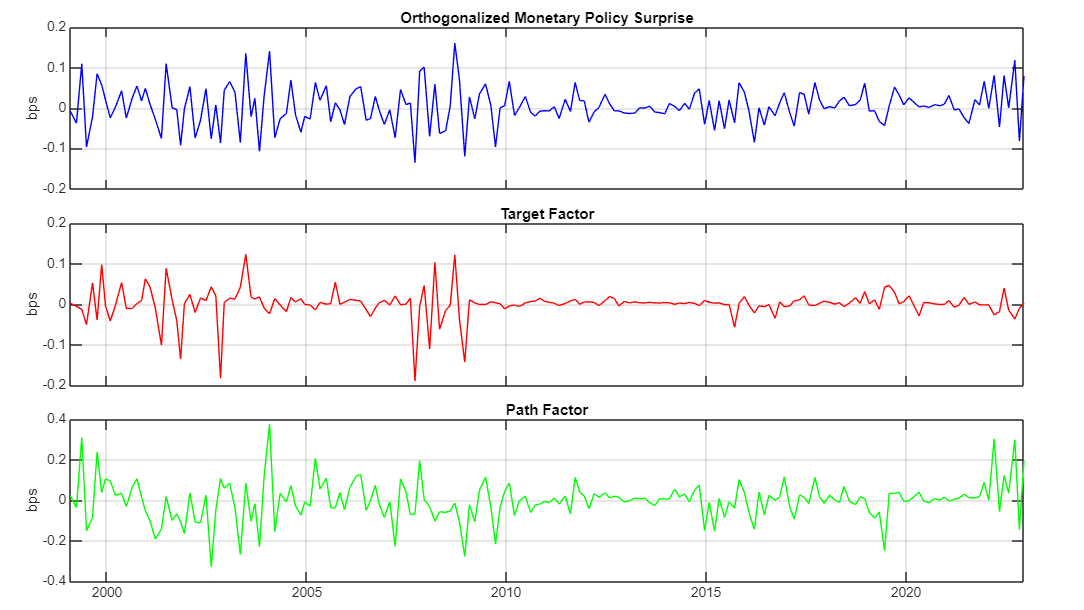

% We plot the series
f0 = figure("Units","normalized","Position",[0,0,1,1]);
t = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
nexttile
plot(mps_base.Dates, mps_base.MPS,'b'); title("Orthogonalized Monetary Policy Surprise");
ylabel("bps"); xticklabels({}); grid on;
nexttile
plot(mps_base.Dates, mps_base.Target,'r'); title("Target Factor");
ylabel("bps"); xticklabels({}); grid on;
nexttile
plot(mps_base.Dates, mps_base.Path, 'g'); title("Path Factor");
ylabel("bps"); grid on;
exportgraphics(f0, 'graphs/factors.pdf', 'ContentType', 'vector');

#### 1.1.2. Event-study

We assess the effect of MPSs on asset prices and zero coupon yields via the two following regressions:

- 
$$\Delta Y_t = \alpha + \beta_{MPS} . MPS_t + \varepsilon_t$$


- 
$$\Delta y_t = \alpha + \beta_t . Target_t + \beta_P . Path_t + \varepsilon_t$$


With $\Delta y_t$ the daily change in a given asset price or ZC nominal interest rates on 2,5 and 10 year maturities.  We got the daily SP500 close price from Yahoo Finance and the ZC nominal yields from Gürkaynak, Sack and Wright (available from Fed website)

% SP500 daily log-returns
raw_dataset_sp500 = readtable("data\sp500_daily.xlsx");

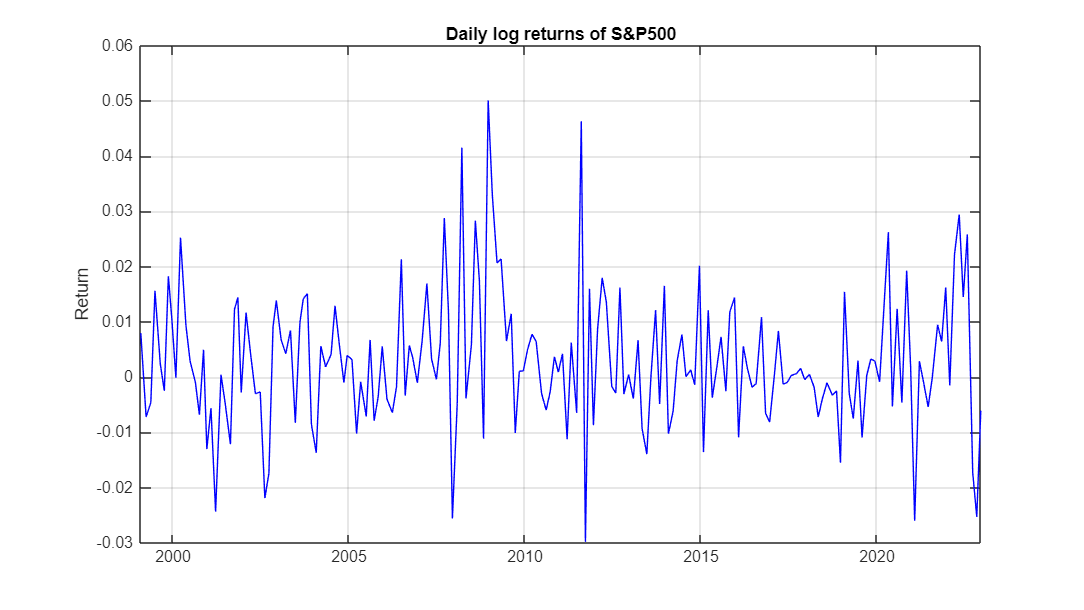

sp500_ret = diff(log(raw_dataset_sp500.GSPC_Close),1);
sp500_dataset = table(raw_dataset_sp500.index_GSPC_(2:length(raw_dataset_sp500.index_GSPC_)),...
    sp500_ret, 'VariableNames',{'Dates','SP500_returns'});

% Outerjoin to make sure that if data is missing from sp500_dataset, it
% won't affect the other columns of mps_base.
mps_base = outerjoin(mps_base, sp500_dataset, 'Keys', 'Dates', 'MergeKeys', true, 'Type', 'left');

% Plot
f1 = figure("Units","normalized","Position",[0,0,1,1]);
plot(mps_base.Dates, mps_base.SP500_returns, 'b'); title("Daily log returns of S&P500");
ylabel('Return'); grid on;
exportgraphics(f1, 'graphs/SP500.pdf', 'ContentType', 'vector');

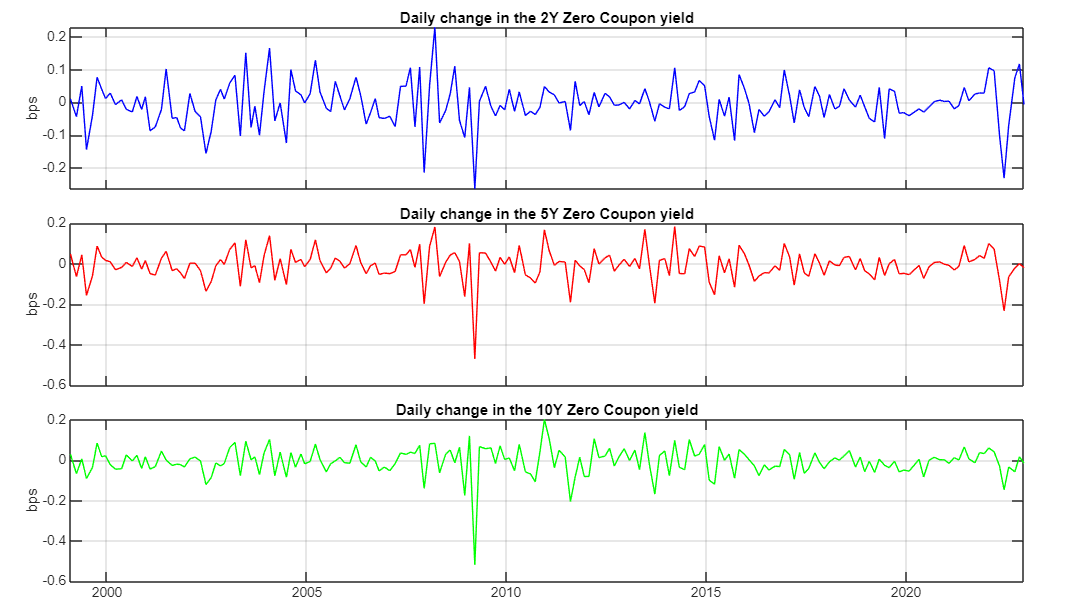

% Import Gurkaynak, Sack and Wright data (available from Fed website)
raw_dataset_gsw = readtable("data\GSW_feds200628.xlsx");
raw_dataset_gsw.Date = datetime(raw_dataset_gsw.Date, 'InputFormat', 'yyyy-MM-dd');

% Keep only values for 2, 5 and 10 year on from 1999-2022
dataset_yields = raw_dataset_gsw(raw_dataset_gsw.Date >= '01-Jan-1999' & raw_dataset_gsw.Date < '01-Jan-2023', ...
    ["Date", "SVENY02","SVENY05","SVENY10"]);

% Compute the daily change in nominal yields
yields_diff = diff(dataset_yields{:, 2:end}); 

% Create table 
yield_base = table(dataset_yields.Date(2:end), yields_diff(:,1), yields_diff(:,2), yields_diff(:,3), ...
    'VariableNames',{'Dates', 'Diff2y', 'Diff5y', 'Diff10y'});

% Merge into mps_base using Left Join
mps_base = outerjoin(mps_base, yield_base, 'Keys', 'Dates', 'MergeKeys', true, 'Type', 'left');

% Plot 
f2 = figure("Units","normalized","Position",[0,0,1,1]);
t = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
nexttile
plot(mps_base.Dates, mps_base.Diff2y,'b'); title("Daily change in the 2Y Zero Coupon yield");
ylabel("bps"); xticklabels({}); grid on;

nexttile
plot(mps_base.Dates, mps_base.Diff5y,'r'); title("Daily change in the 5Y Zero Coupon yield");
ylabel("bps"); xticklabels({}); grid on;

nexttile
plot(mps_base.Dates, mps_base.Diff10y, 'g'); title("Daily change in the 10Y Zero Coupon yield");
ylabel("bps"); grid on;
exportgraphics(f2, 'graphs/changes_in_ZC_yields.pdf', 'ContentType', 'vector');

We now conduct the regressions (endogenous variables are in basis points). It corresponds to table 1 in the paper.

Y_assets = [mps_base.SP500_returns*100, mps_base.Diff2y, mps_base.Diff5y, mps_base.Diff10y];
X_mps = mps_base.MPS;
X_tp = [mps_base.Target, mps_base.Path];

disp("========== STANDARD MP EFFECTS ==========")

========== STANDARD MP EFFECTS ==========


display_regression_results(Y_assets, {X_mps, X_tp}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS'}, {'Target', 'Path'}}, ...
    'SpecNames', {'Baseline', 'Decomposition'}, ...
    'Title', 'Table 1: Standard Monetary Policy effects');


Table 1: Standard Monetary Policy effects

======= Baseline ======= 

               SP500         2y         5y         10y   
              ________    ________    _______    ________

    MPS        -4.6071     0.64176    0.55212     0.30639
    se_MPS      1.8268    0.086954    0.10802     0.10443
    R2        0.032556     0.22373    0.12145    0.043564
    Obs            191         191        191         191


P-values:
                 SP500          2y            5y           10y   
                ________    __________

Compared to the paper:

- The coefficient associated with the S&P 500 is always found to be significative at 5%

- With the MPS regression, all the coefficients associated with the yield are found to be significative at the 0.01 threshold

- With the path / target regression: target is only significative for the 2 year ZC, while Path is highly significative for all ZC.

Similarly to what the authors note, the R-squared explain only a small fraction of the variance of these asset prices, even though FOMC should be the main market mover of bond yields.

### *1.2. Target and Path surprises do not discriminate *future *policy*

The authors, in order to better grasp the information conveyed by the Target and Path surprises, they run the following regressions on each of the federal funds/ Eurodollar futures contracts $F_t^k$ used to construct MPS and their decomposition:


$$\Delta F_t^k = \alpha + \beta_{MPS} \cdot MPS_t + \epsilon_t$$
 


$$\Delta F_t^k = \alpha + \beta_{T} \cdot Target_t + \epsilon_t$$



$$\Delta F_t^k = \alpha + \beta_{P} \cdot Path_t + \epsilon_t$$
    

% For clarity and safety, we constitute a new table composed of the elements we need
FF_eurodollar_base = table(mps_base.Dates, mps_base.MPS, mps_base.Target, mps_base.Path, ...
    mps_base.Target + mps_base.Path, dataset_merged.FF1, dataset_merged.ED1, dataset_merged.ED2,...
    dataset_merged.ED3, dataset_merged.ED4);
FF_eurodollar_base.Properties.VariableNames = ["Dates", "MPS_BS", "Target", "Path", "MPS_GSS",...
    "FF1", "ED1", "ED2", "ED3", "ED4"];
% There are "NA" values (considered as text by MATLAB)
varsRates = ["FF1","ED1","ED2","ED3","ED4"];
for v = varsRates
    FF_eurodollar_base.(v) = str2double(string(FF_eurodollar_base.(v)));
end
disp(sum(isnan(FF_eurodollar_base{:, varsRates})));

    88     0     0     0     0



In the dataset at our disposal (from Bauer & Swanson), we do not have data about FF1 until 2010. We ignore it for now.

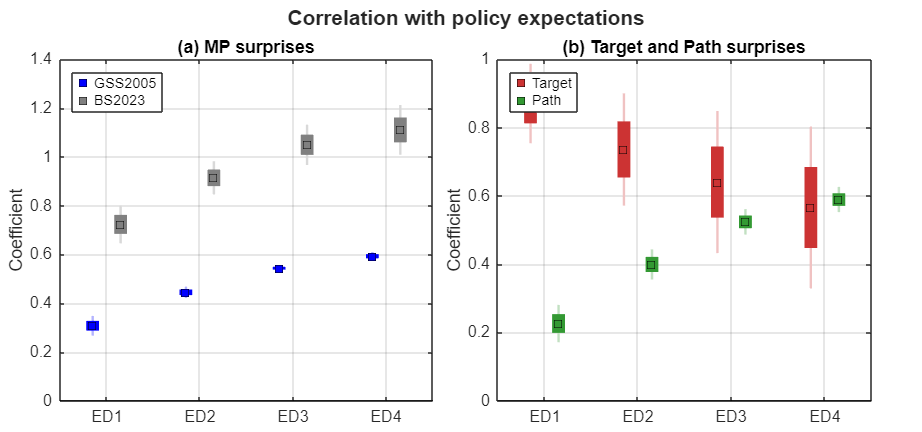

plot_ci(FF_eurodollar_base(:, FF_eurodollar_base.Properties.VariableNames ~= "FF1"))

Results obtained are different from those of the authors, which may be due to the nature of the data: we have intraday changes in Eurodollars, while they use daily changes. Nonetheless, the results we obtain can be interpreted the same way as the authors: target surprises reflect information about both the current and the future policy stance while path surprises seem to only convey information about future stance.

### *1.3. Policy stance vs. high-order moments news*

The authors argue that the "information about the future" contained in the Target factor is a first-order moment news about future policy, i.e. information directly concerning future MP stance. The information contained in the Path factor is by construction orthogonal to that; they argue it conveys higher-order moments surronding the expected policy path (= uncertainty about the policy). In line with standard term structure theory:

- the "information about the future" contained in the Target factor is linked to the expectation of future policy rates

- the information contained in the Path factor is linked to the term premium

If Target and Path are of opposite sign, it means that hawkish / dovish surprises do not have the same effect on the entire term structure. It could induce arbitrage if term premium doesn't adjust. Same-sign Target-Path shocks identify standard policy stance transmission, whereas opposite-sign shocks reveal changes in uncertainty and term premia, allowing identification of higher-order moment news.

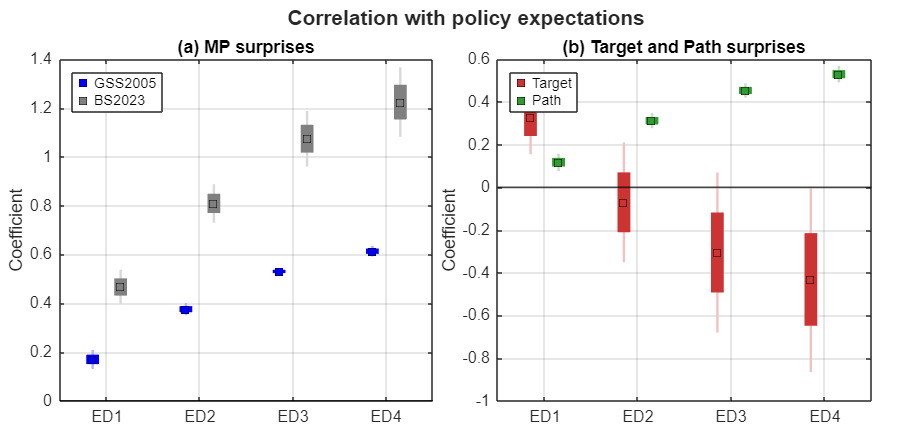

% We create indicators corresponding to opposite signs (and for later, to
% attenuation and high-order moments)
[indic_opp, indic_att, indic_hom] = classifier_mp_events(mps_base);
plot_ci(FF_eurodollar_base(indic_opp, FF_eurodollar_base.Properties.VariableNames ~= "FF1"))

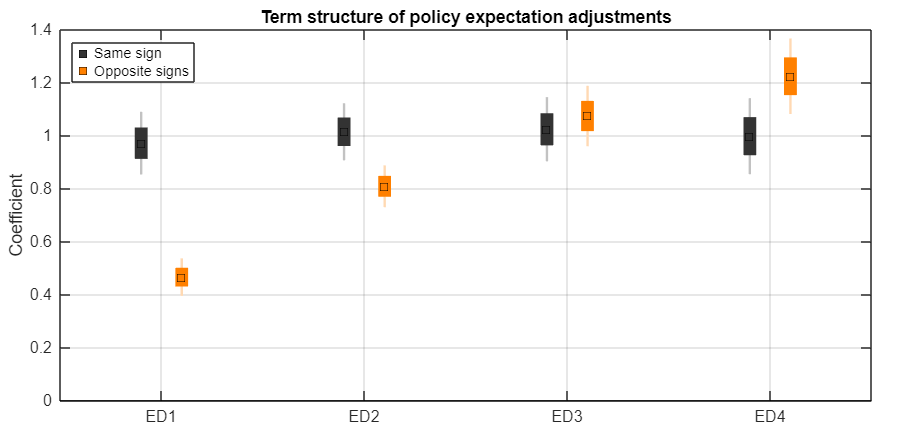

plot_figure2(FF_eurodollar_base(:, FF_eurodollar_base.Properties.VariableNames ~= "FF1"), indic_opp);

We again do not have exactly the same values as the authors but the same interpretation. 

### *1.4. Monetary policy transmission with same vs. opposite signs*

To analyze the importance of the "opposite sign" element, the following regression is conducted:


$$\Delta Y_t = \alpha + \beta_1 MPS_t + \beta_2 \cdot MPS_t \cdot \mathbb{1}_t^{Opp} + \beta_3 \cdot \mathbb{1}_t^{Opp} + \epsilon_t$$


X_opp = [mps_base.MPS mps_base.MPS.* indic_opp indic_opp]

X_opp =    -0.0080         0         0
   -0.0371         0         0
    0.1098    0.1098    1.0000
   -0.0963         0         0
   -0.0221   -0.0221    1.0000
    0.0850    0.0850    1.0000
    0.0570         0         0
    0.0200    0.0200    1.0000
   -0.0242   -0.0242    1.0000
    0.0027    0.0027    1.0000


display_regression_results(Y_assets, {X_opp}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_opp', 'indic_opp'}}, ...
    'Title', 'Table 2: Monetary Policy effects with same or opposite sign');


Table 2: Monetary Policy effects with same or opposite sign

======= Spec1 ======= 

                           SP500         2y            5y           10y    
                          ________    _________    __________    __________

    MPS                    -7.5437       0.3952       0.29023      0.065616
    se_MPS                  2.5557      0.12014       0.15033       0.14556
    MPS x indic_opp         5.8596      0.49626       0.52987        0.4871
    se_MPS x indic_opp      3.6337      0.17081       0.21374       0.20696
    indic_opp              0.18951    0.0038197    -0.0037574    -0.003270

We again obtain very similar results to those of the authors (our standard errors are slightly different though).

The authors also compute descriptive statics for monetary surprises based on the signs

% Table for descriptive statistics result (Table 3 of the paper)
same_sign_mps = mps_base(indic_opp==0,:); 
opposite_sign_mps = mps_base(indic_opp,:);
rowNames = {'Same Signs','Opposite Signs'};
colNames = {'N','%','Mean','Mean Abs','SD'};
table3 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);
table3{1,:} = [height(same_sign_mps), ...
               round(100 * height(same_sign_mps) / height(mps_base), 1), ...
               round(mean(same_sign_mps.MPS), 3), ...
               round(mean(abs(same_sign_mps.MPS)), 3), ...
               round(std(same_sign_mps.MPS), 3)];

table3{2,:} = [height(opposite_sign_mps), ...
               round(100 * height(opposite_sign_mps) / height(mps_base), 1), ...
               round(mean(opposite_sign_mps.MPS), 3), ...
               round(mean(abs(opposite_sign_mps.MPS)), 3), ...
               round(std(opposite_sign_mps.MPS), 3)];

disp('Table 3: Descriptive Statistics');

Table 3: Descriptive Statistics


disp(table3)

                       N      %      Mean     Mean Abs     SD  
                      ___    ____    _____    ________    _____

    Same Signs         90    47.1    0.004     0.038       0.05
    Opposite Signs    101    52.9    0.005     0.032      0.046



The standard deviation we have are slightly higher, but overall, our descriptive statistics are in line with those reported by the authors.

### *1.5. Monetary policy transmission with high-order moment signals*

We now move to the following distinctions:

- attenuation statements: when Target and Path have different signs and Target's magnitude is larger than Path surprise's one,  then the variation in the slope of the term structure of anticipations is mostly due to the policy stance shock

- high-order moment statements: when Target and Path have different signs and Target's magnitude is smaller than Path surprise's one, then the variation in the slope of the term structure of anticipations is mostly due to the uncertainty shock.

They run the following regression to analyze the heterogenous transmission of monetary policy on asset prices:


$$\Delta Y_t = \alpha + \beta_1 MPS_t + \beta_2 MPS_t \cdot 1_t^{Att} + \beta_3 MPS_t \cdot 1_t^{HOM} + \beta_4 \cdot 1_t^{Att} + \beta_5 \cdot 1_t^{HOM} + \epsilon_t$$


X_att_hom = [mps_base.MPS mps_base.MPS.* indic_att mps_base.MPS.* indic_hom indic_att indic_hom];
const = ones(height(mps_base), 1);
display_regression_results(Y_assets, {X_att_hom}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 3: Monetary Policy effects with higher-order moment signals');


Table 3: Monetary Policy effects with higher-order moment signals

======= Spec1 ======= 

                            SP500          2y            5y           10y    
                          _________    __________    __________    __________

    MPS                     -7.5437        0.3952       0.29023      0.065616
    se_MPS                   2.5547       0.11911       0.14943        0.1452
    MPS x indic_att          13.492          0.14     -0.012244     -0.039605
    se_MPS x indic_att       6.6285       0.30904       0.38773       0.37674
    MPS x indic_hom           4.349       0.54927       


% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 
% Attenuation statements
rowNames_Att = {'Marginal_Att', 'se_att'};
table_me_att = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Att, 'VariableNames', colNames);
table_me_att = me_results(Y_assets, [const X_att_hom], table_me_att, [2, 3]);

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_assets, [const X_att_hom], table_me_hom, [2, 4]);
disp('===== Marginal Effect: Attenuation ====');

===== Marginal Effect: Attenuation ====


disp(table_me_att);

                    SP500     2y       5y       10y 
                    _____    _____    _____    _____

    Marginal_Att    5.948    0.535    0.278    0.026
    se_att          6.116    0.285    0.358    0.348




disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -3.195    0.944    0.918    0.661
    se_hom           2.862    0.133    0.167    0.163




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_assets(~indic_opp,:), mps_base.MPS(~indic_opp), true);
[~, ~, r2_att, n_att] = robust_ols(Y_assets(indic_att,:), mps_base.MPS(indic_att), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_assets(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_att; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Same Sign', 'R2 Att', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                     SP500         2y          5y          10y    
                    ________    ________    ________    __________

    R2 Same Sign    0.092777    0.095942     0.04866     0.0033346
    R2 Att          0.042983     0.15205    0.037154    0.00039435
    R2 HOM          0.015587     0.44841     0.23907       0.13062
    Obs                  191         191         191           191



We now seek to analyze the differentiated effects of HOM statements VS other statements on changes in Treasury yields

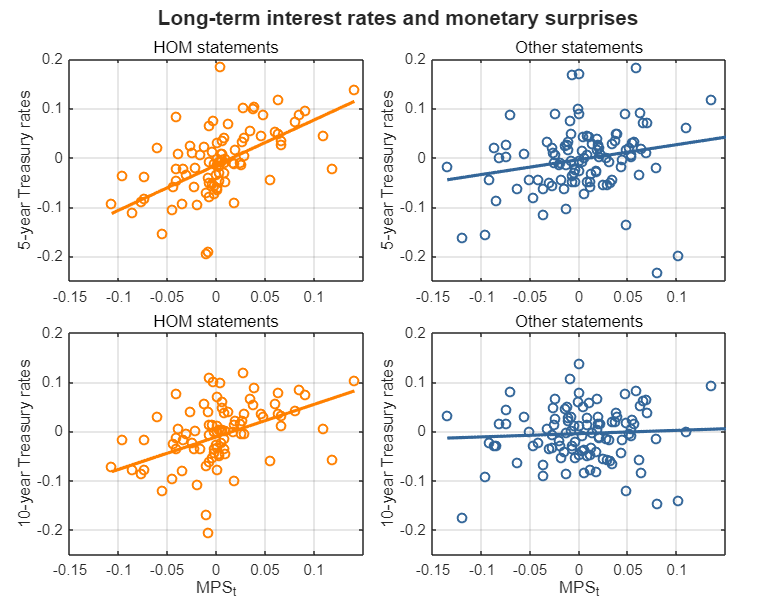

nominal_yields_base = raw_dataset_gsw(raw_dataset_gsw.Date > '01-Jan-1999' & ...
raw_dataset_gsw.Date < '01-Jan-2023', ...
    ["Date", "SVENY01", "SVENY02", ...
    "SVENY03", "SVENY04", "SVENY05", "SVENY06", ...
    "SVENY07", "SVENY08", "SVENY09", "SVENY10", ...
    "SVENY11", "SVENY12", "SVENY13", "SVENY14", "SVENY15", ...
    "SVENY20","SVENY25","SVENY30"]);

% If there are missing values, we forward fill
nominal_yields_base = fillmissing(nominal_yields_base, 'previous');

% Compute the daily change in nominal yields and keep the matching dates
diff_yield = diff(nominal_yields_base(:,2:size(nominal_yields_base.Properties.VariableNames,2)),1);
annual_yield_base = table(nominal_yields_base.Date(2:length(nominal_yields_base.Date)),...
    'VariableNames',{'Dates'});
annual_yield_base = [annual_yield_base, diff_yield];
match_dates_yield = ismember(annual_yield_base.Dates,  mps_base.Dates);
annual_yield_base = annual_yield_base(match_dates_yield,:);
[~, idx_yields, idx_mps] = intersect(annual_yield_base.Dates, FF_eurodollar_base.Dates);
yields_final = annual_yield_base(idx_yields, :);
mps_final    = FF_eurodollar_base(idx_mps, :);

% Figure 3 
plot_figure3(yields_final, mps_final, indic_hom);

As the authors, we find that, for HOM statements, the relationship is much steeper and data points for HOM statements are much more clustered around the regression line, which means the relationship is more meaningful.

 We now replicate one of the main result of the paper, displayed in their Table 5. That is, the heterogenous effects of MPS on (long-term) interest rates depending on the interplay between Target and Path factors.

Y_yields = table2array(yields_final(:, 2:end));
X_att_hom = [mps_base.MPS mps_base.MPS.* indic_att mps_base.MPS.* indic_hom indic_att indic_hom];
const = ones(height(mps_base), 1);
colNames = {'1y', '2y', '3y', '4y', '5y', '6y', '7y', '8y', '9y', '10y', '11y', '12y', '13y', '14y',...
                                '15y', '20y', '25y', '30y'};
display_regression_results(Y_yields, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 5: MPS effects on nominal yields at various maturities');


Table 5: MPS effects on nominal yields at various maturities

======= Spec1 ======= 

                             1y            2y            3y           4y            5y            6y            7y            8y            9y           10y           11y           12y            13y            14y           15y          20y           25y          30y   
                          _________    __________    __________    _________    __________


% Marginal effects of MPS for HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);

table_me_hom = me_results(Y_yields, [const X_att_hom], table_me_hom, [2, 4]);
disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                     1y       2y       3y       4y       5y       6y       7y       8y       9y       10y      11y      12y      13y      14y      15y      20y      25y      30y 
                    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

    Marginal_Hom


% R2 on the subsamples
[~, ~, r2_other, ~] = robust_ols(Y_yields(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, ~]  = robust_ols(Y_yields(logical(indic_hom),:), mps_base.MPS(logical(indic_hom)), true);

results_r2_subsamples = [r2_other; r2_hom; repmat(height(Y_yields), 1, width(Y_yields))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);

disp(' ==== Table 5: R2 Decomposition (Same vs HOM) ====');

 ==== Table 5: R2 Decomposition (Same vs HOM) ====


disp(table_r2_final);

                  1y         2y          3y          4y          5y          6y          7y          8y          9y           10y          11y          12y           13y           14y           15y          20y         25y         30y   
                _______    _______    ________    ________    ________    ________    ________    ________    _________    _________    _________    __________    __________    __________    _________ 

Results are, again, close to the authors'.

### *1.6. Asset price responses in a narrow window*

We previously used daily changes in interest rates to analyze monetary policy surprise effects. Now, we use the database provided by Bauer & Swanson which contains intraday changes (30-min window around the FOMC annoucements). We do not have intraday changes of the S&P500 for the whole period.

% Now we do the regression
varsRates = ["SP500Emini","TNOTE02","TNOTE05","TNOTE10"];
for v = varsRates
    dataset_merged.(v) = str2double(string(dataset_merged.(v)));
end
Y_narrow = [dataset_merged.SP500Emini dataset_merged.TNOTE02 dataset_merged.TNOTE05 dataset_merged.TNOTE10];
const = ones(height(mps_base), 1);

display_regression_results(Y_narrow, {X_att_hom}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 3: Monetary Policy effects with higher-order moment signals');


Table 3: Monetary Policy effects with higher-order moment signals

======= Spec1 ======= 

                            SP500          2y            5y           10y    
                          _________    __________    __________    __________

    MPS                      -6.805       0.68002       0.52648       0.30255
    se_MPS                  0.96505      0.059168      0.075064      0.070653
    MPS x indic_att          4.3232     -0.056149      0.023483     0.0031206
    se_MPS x indic_att        2.504       0.15352       0.19477       0.18332
    MPS x indic_hom         0.78424       0.34688       


% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_narrow, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -6.021    1.027    1.046    0.758
    se_hom           1.081    0.066    0.084    0.079




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_narrow(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_narrow(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                 SP500       2y         5y         10y  
                _______    _______    _______    _______

    R2 Other    0.33165     0.5838    0.39999    0.26194
    R2 HOM      0.25707    0.75497    0.60474    0.41941
    Obs             191        191        191        191



Results are quite different (notably the interaction coef for SP500), to check but it might be due differences in the data...

### *1.7. Euro area evidence*

We redo the same work but on Euro area data. 

raw_eu_mpd_dataset = readtable('data\Dataset_EA-MPD.xlsx', 'Sheet', 'Press Release Window');
raw_eu_mpd_dataset.date = datetime(raw_eu_mpd_dataset.date);
mask = raw_eu_mpd_dataset.date>= datetime(1999,1,1) & raw_eu_mpd_dataset.date <= datetime(2023,10,31);
eu_mpd_dataset = raw_eu_mpd_dataset(mask,:);

% Factors construction
eu_target = eu_mpd_dataset.OIS_1M;
mdl = fitlm(eu_target, eu_mpd_dataset.OIS_1Y);
eu_path = mdl.Residuals.Raw;
eu_target = eu_target./std(eu_target);
eu_path = eu_path./std(eu_path);
disp(['Target/Path correlation: ', num2str(corr(eu_target, eu_path))]);

Target/Path correlation: 7.7492e-17


mps_base_eu = table(eu_target, eu_path, 'VariableNames', {'Target','Path'});
mps_base_eu.Total = eu_mpd_dataset.OIS_1Y;

% Indicators for HOM statements
[indic_opp_eu, indic_att_eu, indic_hom_eu] = classifier_mp_events(mps_base_eu);

% Regressions
Y_eu = [eu_mpd_dataset.STOXX50 eu_mpd_dataset.DE2Y eu_mpd_dataset.DE5Y eu_mpd_dataset.DE10Y];
X_att_hom_eu = [mps_base_eu.Total mps_base_eu.Total.* indic_att_eu ...
                mps_base_eu.Total.* indic_hom_eu indic_att_eu indic_hom_eu];
const = ones(height(mps_base_eu), 1);
display_regression_results(Y_eu, {X_att_hom_eu}, ...
    'YNames', {'STOXX50', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 8: Euro area evidence');


Table 8: Euro area evidence

======= Spec1 ======= 

                           STOXX50         2y          5y          10y   
                          __________    ________    _________    ________

    MPS                    -0.058847     0.84427      0.58782     0.19831
    se_MPS                 0.0094002    0.034905     0.041657    0.040697
    MPS x indic_att        0.0083712    -0.43107     -0.54982    -0.37726
    se_MPS x indic_att      0.023219    0.086218       0.1029     0.10052
    MPS x indic_hom         0.018625     0.35444      0.67563     0.66659
    se_MPS x indic_hom     


% Marginal effects of MPS depending on the type of statement

colNames = {'STOXX50', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_eu, [const X_att_hom_eu], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    STOXX50     2y       5y       10y 
                    _______    _____    _____    _____

    Marginal_Hom     -0.04     1.199    1.263    0.865
    se_hom           0.021     0.079    0.095    0.092




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_eu(~indic_hom_eu,:), mps_base_eu.Total(~indic_hom_eu), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_eu(indic_hom_eu,:), mps_base_eu.Total(indic_hom_eu), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_eu), 1, width(Y_eu))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                STOXX50       2y         5y         10y   
                ________    _______    _______    ________

    R2 Other     0.15434    0.69513    0.39374    0.052056
    R2 HOM      0.068667    0.79142    0.75392     0.59333
    Obs              299        299        299         299



### *1.8. The information content of high-order moment statements*

We have confirmed that monetary surprises from HOM statements have a significant effect on long term interest rates, like the authors. In theory, monetary policy only has a temporary effect on real variables, and is neutral in the long run, so the authors investigate what drives its influence on long-term interest rates. This section aims to understand what information is learned by the markets from HOM statements.

#### 1.8.1. Real rates and inflation compensation

First they decompose the nominal yields into real yields (via TIPS) and inflation compensation (via break-even inflation rates). 

raw_tips_dataset = readtable('data\feds200805.xlsx');
raw_tips_dataset.Date = datetime(raw_tips_dataset.Date);
mask = raw_tips_dataset.Date>= datetime(1999,1,1) & raw_tips_dataset.Date <= datetime(2023,10,31);
tips_dataset = raw_tips_dataset(mask,:);
tips_changes = diff(tips_dataset(:,2:size(tips_dataset,2)), 1);
tips_changes_dataset = array2table(tips_dataset.Date(2:size(tips_dataset,1)), ...
    'VariableNames',{'Dates'});
tips_changes_dataset = [tips_changes_dataset tips_changes];
match_dates_tips = ismember(tips_changes_dataset.Dates,  mps_base.Dates);
tips_changes_dataset = tips_changes_dataset(match_dates_tips, :);

% Regressions
Y_tips = [yields_final.SVENY02, yields_final.SVENY05, yields_final.SVENY10,...
    tips_changes_dataset.TIPSY02, tips_changes_dataset.TIPSY05, tips_changes_dataset.TIPSY10 ...
    tips_changes_dataset.BKEVEN02 tips_changes_dataset.BKEVEN05 tips_changes_dataset.BKEVEN10];
colNames = {'NIR-2y','NIR-5y','NIR-10y','RIR-2y',...
    'RIR-5y','RIR-10y','IC-2y','IC-5y','IC-10y'}

colNames = 1×9 cell array
    {'NIR-2y'}    {'NIR-5y'}    {'NIR-10y'}    {'RIR-2y'}    {'RIR-5y'}    {'RIR-10y'}    {'IC-2y'}    {'IC-5y'}    {'IC-10y'}


display_regression_results(Y_tips, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 9: Decomposition of nominal interest rates: real rates and inflation compensation');


Table 9: Decomposition of nominal interest rates: real rates and inflation compensation

======= Spec1 ======= 

                            NIR-2y        NIR-5y       NIR-10y       RIR-2y        RIR-5y       RIR-10y       IC-2y         IC-5y        IC-10y  
                          __________    __________    __________    _________    __________    _________    __________    __________    _________

    MPS                       0.3952       0.29023      0.065616     -0.39225       0.17055      0.11589    


% Marginal effects of MPS depending on the type of statement
% HOM statements
const = ones(height(mps_base), 1);
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
     'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_tips, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    NIR-2y    NIR-5y    NIR-10y    RIR-2y    RIR-5y    RIR-10y    IC-2y     IC-5y    IC-10y
                    ______    ______    _______    ______    ______    _______    ______    _____    ______

    Marginal_Hom    0.944     0.918      0.661     1.315     0.856      0.673     -0.371    0.062    -0.012
    se_hom          0.133     0.167      0.163     0.431     0.203      0.169      0.397    0.111     0.079



 
% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_tips(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_tips(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_tips), 1, width(Y_tips))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                NIR-2y      NIR-5y      NIR-10y      RIR-2y       RIR-5y     RIR-10y      IC-2y        IC-5y         IC-10y  
                _______    ________    _________    _________    ________    ________    ________    __________    __________

    R2 Other    0.10976    0.050723    0.0032683    0.0014033    0.035774    0.025107    0.023222    3.2255e-06       0.02785
    R2 HOM      0.44841     0.23907      0.13062      0.14388     0.15024      0.1235     0.01732     0.0038932    0.00036272
    Obs             191         191          191          191         191         191         191           191           191



#### 1.8.2. Expectation hypothesis vs. term premium 

We now move to the standard nominal yield decomposition based on the ACM model: nominal yield is composed of:

- an expectation hypothesis component

- a term premium component, given in the ACM database

% Import the ACM database and align dates 
raw_acm = readtable('data\ACMTermPremium.xls', 'Sheet', 'ACM Daily');
raw_acm.DATE = datetime(raw_acm.DATE);
acm_changes = diff(raw_acm(:,2:size(raw_acm,2)), 1);
acm_changes_dataset = array2table(raw_acm.DATE(2:size(raw_acm.DATE,1)), ...
    'VariableNames',{'Dates'});
acm_changes_dataset = [acm_changes_dataset acm_changes];
match_dates_fftr = ismember(acm_changes_dataset.Dates, mps_base.Dates);
acm_changes_dataset = acm_changes_dataset(match_dates_fftr,:);

% We create expectation hypothesis change estimates as the difference
% between nominal yield and term premium
eh_changes = table(acm_changes_dataset.ACMY02 - acm_changes_dataset.ACMTP02,...
    acm_changes_dataset.ACMY05 - acm_changes_dataset.ACMTP05,...
    acm_changes_dataset.ACMY10 - acm_changes_dataset.ACMTP10,...
    'VariableNames', {'ACMEH02', 'ACMEH05', 'ACMEH10'});

% Regressions
Y_acm = [acm_changes_dataset.ACMY02, acm_changes_dataset.ACMY05, acm_changes_dataset.ACMY10,...
    eh_changes.ACMEH02, eh_changes.ACMEH05, eh_changes.ACMEH10,...
    acm_changes_dataset.ACMTP02, acm_changes_dataset.ACMTP05, acm_changes_dataset.ACMTP10];
colNames = {'NIR-2y','NIR-5y','NIR-10y','EH-2y',...
    'EH-5y','EH-10y','TP-2y','TP-5y','TP-10y'}

colNames = 1×9 cell array
    {'NIR-2y'}    {'NIR-5y'}    {'NIR-10y'}    {'EH-2y'}    {'EH-5y'}    {'EH-10y'}    {'TP-2y'}    {'TP-5y'}    {'TP-10y'}


display_regression_results(Y_acm, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 10: Decomposition of nominal interest rates: expectation hypothesis and term premium');


Table 10: Decomposition of nominal interest rates: expectation hypothesis and term premium

======= Spec1 ======= 

                            NIR-2y         NIR-5y       NIR-10y        EH-2y         EH-5y         EH-10y         TP-2y         TP-5y        TP-10y  
                          ___________    __________    __________    __________    __________    __________    ___________    __________    _________

    MPS                       0.39642       0.28997      0.064452       0.52392       0.48721    


% Marginal effects of MPS depending on the type of statement
% HOM statements
const = ones(height(mps_base), 1);
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
     'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_acm, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    NIR-2y    NIR-5y    NIR-10y    EH-2y    EH-5y    EH-10y    TP-2y    TP-5y    TP-10y
                    ______    ______    _______    _____    _____    ______    _____    _____    ______

    Marginal_Hom    0.952     0.919      0.671     0.687    0.754    0.634     0.265    0.166    0.036 
    se_hom          0.133     0.168      0.166     0.123    0.127    0.105     0.076    0.107    0.143 



 
% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_acm(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_acm(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_acm), 1, width(Y_acm))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                NIR-2y      NIR-5y      NIR-10y      EH-2y      EH-5y     EH-10y      TP-2y       TP-5y        TP-10y  
                _______    ________    _________    _______    _______    _______    ________    ________    __________

    R2 Other    0.11034    0.050529    0.0028334    0.19585     0.1666    0.15422    0.041443    0.077824       0.09876
    R2 HOM      0.45723     0.23877      0.12859    0.35956    0.36314    0.35752     0.15176    0.021338    0.00062405
    Obs             191         191          191        191        191        191         191         191           191



Results are overall similar to those of the authors. 

### *1.9. Balance of risks vs risk appetite*

Finally, the authors estimate the effect of MPS on changes in several risk, uncertainty and term premium measures.

% All the data comes from different sources, so aggregating them requires
% the following loop
risk_indicators = {'VIX', 'BBM23', 'BEX21', 'KW05', 'BLM22'};

for i = 1:length(risk_indicators)
    indicator_name = risk_indicators{i};
    % Download raw data
    raw_data = readtable("data\risk_indicators.xlsx", "Sheet", indicator_name);
    raw_data.date = datetime(raw_data.date);
    
    % Forward fill for missing values
    indicator_base = fillmissing(raw_data, 'previous');
    
    % Changes 
    diff_indicator = diff(indicator_base{:, 2:end}, 1);
    indicator_changes = table(indicator_base.date(2:end), ...
                             'VariableNames', {'Dates'});
    var_names = indicator_base.Properties.VariableNames(2:end);
    for j = 1:length(var_names)
        indicator_changes.(var_names{j}) = diff_indicator(:, j);
    end
    
    % Match with MPS dates
    match_dates = ismember(indicator_changes.Dates, mps_base.Dates);
    indicator_changes = indicator_changes(match_dates, :);
    
    % Save dynamically
    eval([indicator_name '_final = indicator_changes;']);
end

% Regressions
Y_risk = [VIX_final.VIX, BEX21_final.index,...
    KW05_final.THREEFYTP0100_B, KW05_final.THREEFFTP0100_B,...
    KW05_final.THREEFYTP1000_B, KW05_final.THREEFFTP1000_B,...,
    BLM22_final.x6Months];
colNames = {'VIX', 'BEX21', 'TP1Y', 'FTP1Y', 'TP10Y', 'FTP10Y', 'BLM22'};
display_regression_results(Y_risk, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 12: Monetary policy effects on various HOM measures');


Table 12: Monetary policy effects on various HOM measures

======= Spec1 ======= 

                            VIX         BEX21         TP1Y         FTP1Y         TP10Y         FTP10Y        BLM22   
                          ________    _________    __________    __________    __________    __________    __________

    MPS                      9.653       2.2706      0.032308      0.056806      0.064455      0.061855       0.13613
    se_MPS                  4.1632      0.76058      0.021914      0.038011      0.058224      0.074304       0.05331
    


% Marginal effects of MPS depending on the type of statement
% HOM statements
const = ones(height(mps_base), 1);
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
     'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_risk, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                     VIX     BEX21     TP1Y     FTP1Y    TP10Y    FTP10Y    BLM22
                    _____    ______    _____    _____    _____    ______    _____

    Marginal_Hom    3.425    -0.057    0.145    0.252    0.341    0.375     0.094
    se_hom          4.665     0.852    0.025    0.043    0.065    0.083      0.06



 
% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_risk(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_risk(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_risk), 1, width(Y_risk))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                   VIX         BEX21         TP1Y       FTP1Y       TP10Y       FTP10Y       BLM22  
                _________    __________    ________    ________    ________    _________    ________

    R2 Other      0.03441      0.059945    0.036468    0.037242    0.020546    0.0091715    0.065403
    R2 HOM      0.0080013    7.4577e-05     0.29287     0.29584     0.21928      0.16177    0.039517
    Obs               191           191         191         191         191          191         191



Results are really coherent with the authors except for BLM22 (probably due to a different measure: what we found is a dataset containing several market-based monetary policy uncertainty indexes, but the authors do not specify the one they use). 

## 2. Robustness checks

### *2.1. Controlling for QE*

J'ai pas les dates des annonces QE ?

### *2.2. Controlling for the type of decision*

We want to see whether the conclusions are robust to the type of decision (hike/cut/hold). 

Federal Fed Target Rate = the one in place before 2009, then the mean between the upper and lower bounds

FFTR = readtable("data\FED_rates.xlsx");
FFTR.Date = datetime(FFTR.Date);
match_dates_fftr = ismember(FFTR.Date, mps_base.Dates);
FFTR_dataset = FFTR(match_dates_fftr,:);
rate = FFTR_dataset.FFTR;
FFTR_dataset.Hike = [false; rate(2:end) > rate(1:end-1)];
FFTR_dataset.Cut = [false; rate(2:end) < rate(1:end-1)];
FFTR_dataset.Hold = [false; rate(2:end) == rate(1:end-1)];
% First decision was to hold
FFTR_dataset.Hold(1) = 1;

% Regression
X_att_hom_dec = [ ...
    mps_base.MPS, ...
    mps_base.MPS.*indic_att, ...
    mps_base.MPS.*indic_hom, ...
    indic_att, ...
    indic_hom, ...
    mps_base.MPS.*FFTR_dataset.Hike, ...
    mps_base.MPS.*FFTR_dataset.Hold, ...
    FFTR_dataset.Hike, ...
    FFTR_dataset.Hold ...
];

const = ones(height(mps_base), 1);
display_regression_results(Y_assets, {X_att_hom_dec}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{ ...
        'MPS', ...
        'MPS x indic_att', ...
        'MPS x indic_hom', ...
        'indic_att', ...
        'indic_hom', ...
        'MPS x Hike', ...
        'MPS x Hold', ...
        'Hike', ...
        'Hold' ...
    }}, ...
    'Title', 'Controlling for the type of decision');


Controlling for the type of decision

======= Spec1 ======= 

                           SP500         2y            5y           10y    
                          ________    _________    __________    __________

    MPS                    -11.032      0.44367       0.32596       0.19564
    se_MPS                   3.472      0.16231       0.20459       0.19838
    MPS x indic_att         12.117     0.075314     -0.086192     -0.061556
    se_MPS x indic_att      6.8706      0.32119       0.40486       0.39257
    MPS x indic_hom        0.61486      0.55827       0.60703       0.67295
    se_MPS x 

% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_assets, [const X_att_hom_dec], table_me_hom, [2, 4]);
disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                     SP500      2y       5y       10y 
                    _______    _____    _____    _____

    Marginal_Hom    -10.417    1.002    0.933    0.869
    se_hom            5.289    0.247    0.312    0.302




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_assets(~indic_opp,:), mps_base.MPS(~indic_opp), true);
[~, ~, r2_att, n_att] = robust_ols(Y_assets(indic_att,:), mps_base.MPS(indic_att), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_assets(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_att; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Same Sign', 'R2 Att', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                     SP500         2y          5y          10y    
                    ________    ________    ________    __________

    R2 Same Sign    0.092777    0.095942     0.04866     0.0033346
    R2 Att          0.042983     0.15205    0.037154    0.00039435
    R2 HOM          0.015587     0.44841     0.23907       0.13062
    Obs                  191         191         191           191



HOM effect stays significant for long term interest rate even with these controls. Meanwhile, control coefficients on Hike and Hold are not significant, which means that heterogenous transmission *does not come* from different type of decisions. 

### *2.X. Extending to more recent data / other monetary events*

J'ai pas l'impression que BS 2023 et USMPD soit cohérents entre eux donc à voir...